# DC motor speed: digital control

## System model

J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2);

## Conversion using ZOH

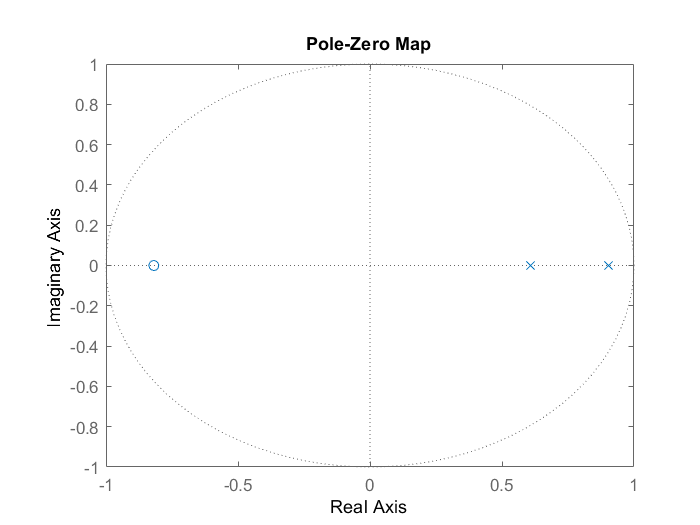

Ts = 0.05;
sys = c2d(P_motor, Ts, 'zoh');
pzmap(sys);

## Controller conversion

Kp = 100;
Ki = 200;
Kd = 20;
C = pid(Kp, Ki, Kd);
C_digital = c2d(C, Ts, 'tustin');

## System response

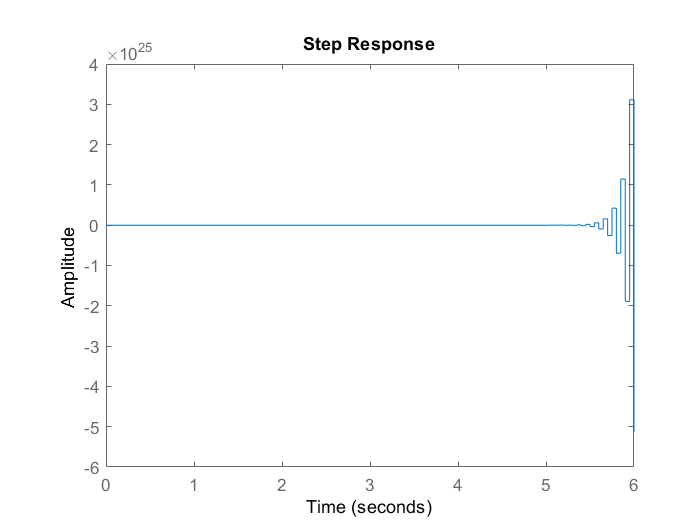

sys_cl = feedback(C_digital*sys, 1);
step(sys_cl);

The system is not stable, then we need to redesign the controller. Look at the root locus of the open-loop system

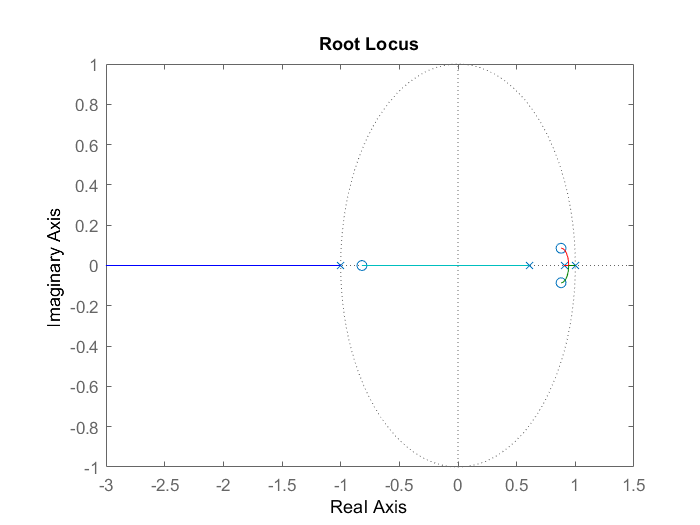

rlocus(sys * C_digital);

There is one pole outside the unit circle and this pole -1 comes from the digital controller, we can pull this pole back to the unit circle by canceling the zero at -0.82, and 

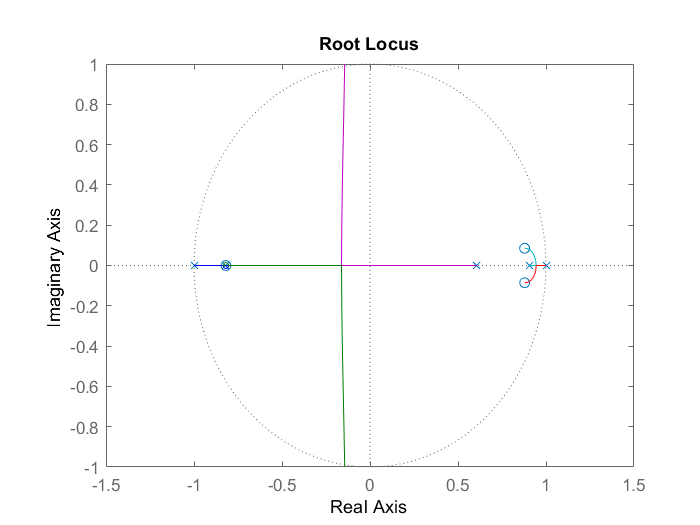

z = tf('z',Ts);
C_digital = C_digital/(z+0.82);
rlocus(sys * C_digital);

## Find the appropriate gain

% [K1,poles] = rlocfind(C_digital * sys);

Finish the design

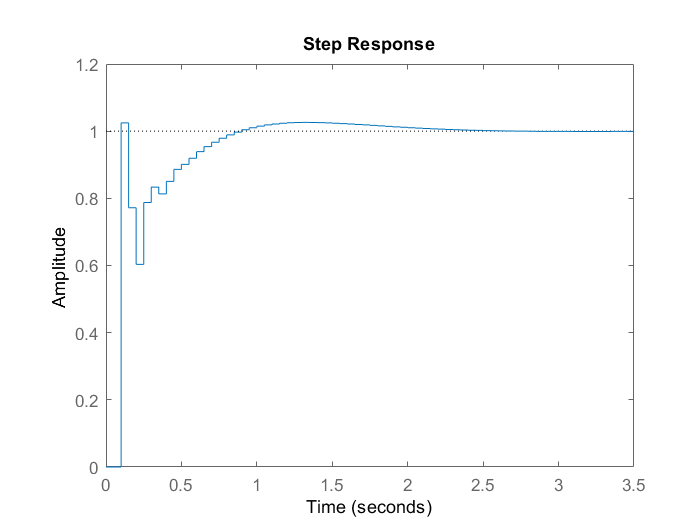

K2 = 0.55;
sys_cl = feedback(K2*sys*C_digital, 1);
step(sys_cl);